x1=[110;130;180;125;150;165;120;145;175;155];
x2=[105;125;85;145;200;160;240;260;290;270];
x=[ones(10,1),x1,x2];%[1 x11 x21]
y=[102;99;115;75;55;95;16;78;82;90];
[b,bint,residual,rint,stats]=regress(y,x)

b =    40.7567
    0.5738
   -0.2316


bint =   -73.1295  154.6429
   -0.1976    1.3451
   -0.4803    0.0171


residual =    22.4463
   12.6028
   -9.3495
   -3.8964
  -25.5028
   -3.3732
  -38.0258
   14.2619
    7.9967
   22.8401


rint =   -17.5555   62.4481
  -39.7317   64.9373
  -43.3415   24.6424
  -57.7776   49.9849
  -76.6777   25.6721
  -57.0559   50.3094
  -70.0603   -5.9914
  -37.5222   66.0459
  -37.4270   53.4204
  -24.6614   70.3416


stats =     0.4874    3.3280    0.0964  523.1453


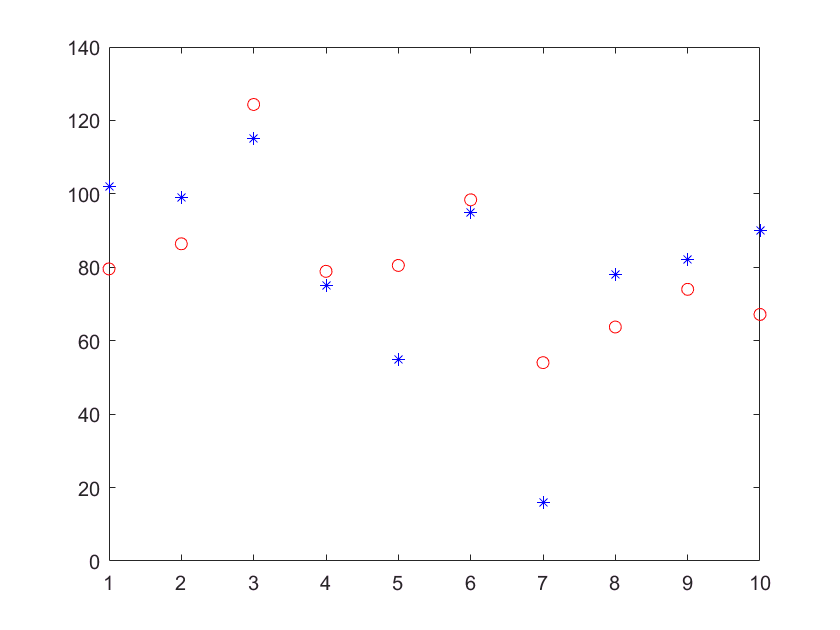

plot(1:10,b(1)+b(2)*x1+b(3)*x2,'ro',1:10,y,'b*')

%rcoplot(residual,rint)%离群
%[b,resnorm,residual]=lsqlin(x,y)

y=[1500;2000;1600];
x=[2 3 4;1 4 5;3 4 2];
rank(x);rank([x,y])

ans = 3

%b=x\y;
lb=[0;0;0];
[b,resnorm,residual]=lsqlin(x,y,[],[],[],[],lb);

Optimization terminated: relative function value changing by less
 than sqrt(OPTIONS.FunctionTolerance), and rate of progress is slow.


[b,resnorm,residual,exitflag]=lsqnonneg(x,y)

b =          0
  336.7347
  127.3469


resnorm = 653.0612

residual =   -19.5918
   16.3265
   -1.6327


exitflag = 1

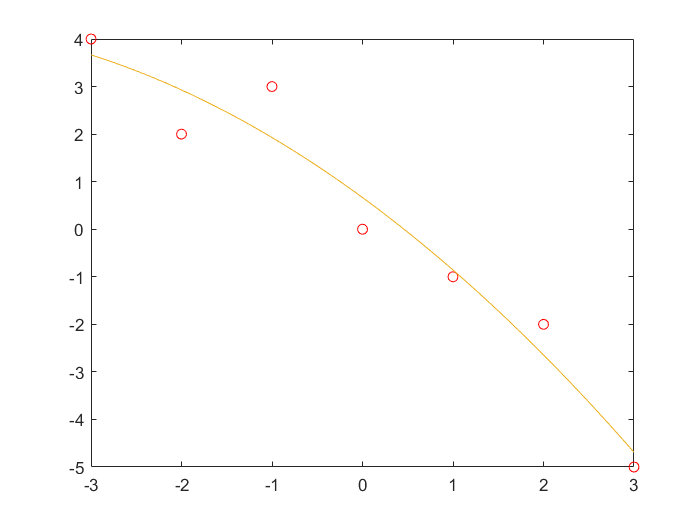

x=[-3 -2 -1 0 1 2 3]';
y=[4 2 3 0 -1 -2 -5]';
[p,s]=polyfit(x,y,2);
plot(x,y,'ro')
yx=@(x)p(1)*x.*x+p(2)*x+p(3);
hold on
fplot(yx,[-3,3])

t=[0 27 40 52 70 89 100]';
y=[100 82.2 76.3 71.8 66.4 63.3 61.3]';
%fun=@(b,x)b(1)*exp(b(2)*x+b(3)*x.*x);
b0=[1 0 0]';
[b,resnorm,residual,exitflag,output]=lsqcurvefit(@funx,b0,t,y)


Local minimum possible.

lsqcurvefit stopped because the size of the current step is less than
the default value of the step size tolerance.

<stopping criteria details>



b =    99.9571
   -0.0080
    0.0000


resnorm = 0.2614

residual =    -0.0429
    0.1386
   -0.0446
   -0.0764
    0.1641
   -0.3831
    0.2426


exitflag = 2

output =     firstorderopt: 0.8292
       iterations: 34
        funcCount: 140
     cgiterations: 0
        algorithm: 'trust-region-reflective'
         stepsize: 2.5892e-07
          message: 'Local minimum possible.…'


ycal=funx(b,t)

ycal =    99.9571
   82.3386
   76.2554
   71.7236
   66.5641
   62.9169
   61.5426


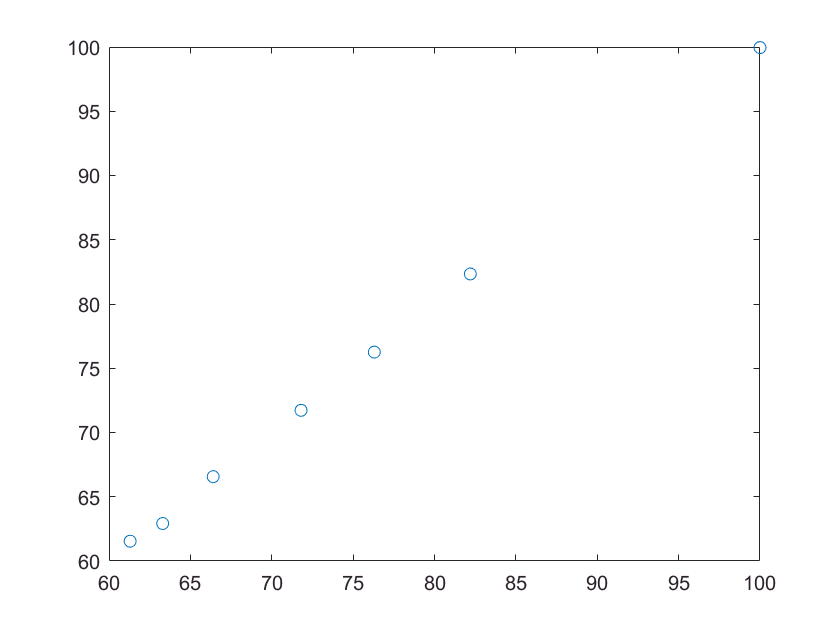

plot(y,ycal,'o')

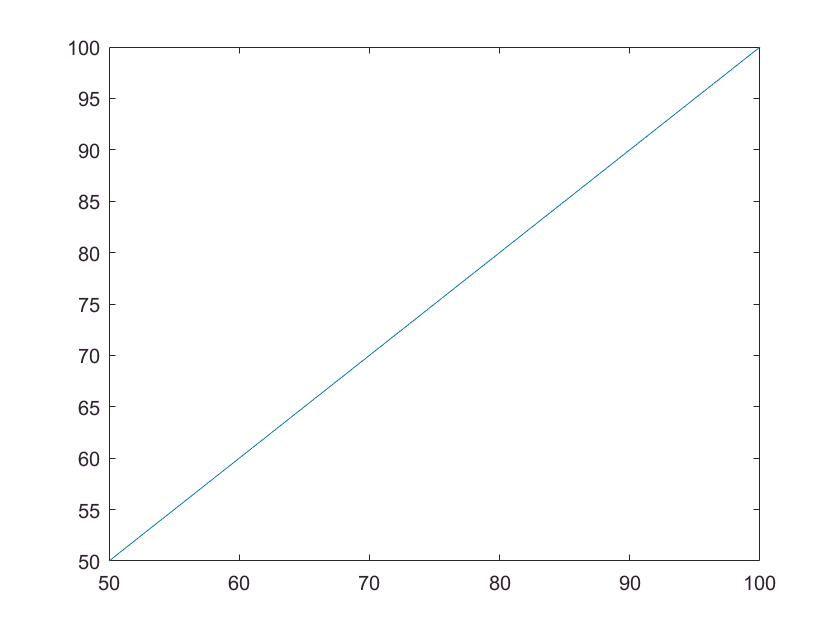

yf=@(x)x; 
fplot(yf,[50,100])

t=1:16;
y=[4 6.4 8 8.8 9.22 9.5 9.7 9.86 10 10.2 10.32 10.42 10.5 10.55 10.58 10.6]';
b0=[1 1];
fun=@(b)b(1)*exp(b(2)./t)-y;
[b,resnorm,residual,exitflag]=lsqnonlin(@(b)funy(b,t,y),b0);%拟合残差出直线


Local minimum found.

Optimization completed because the size of the gradient is less than
the default value of the optimality tolerance.

<stopping criteria details>




Local minimum found.

Optimization completed because the size of the gradient is less than
the default value of the optimality tolerance.

<stopping criteria details>



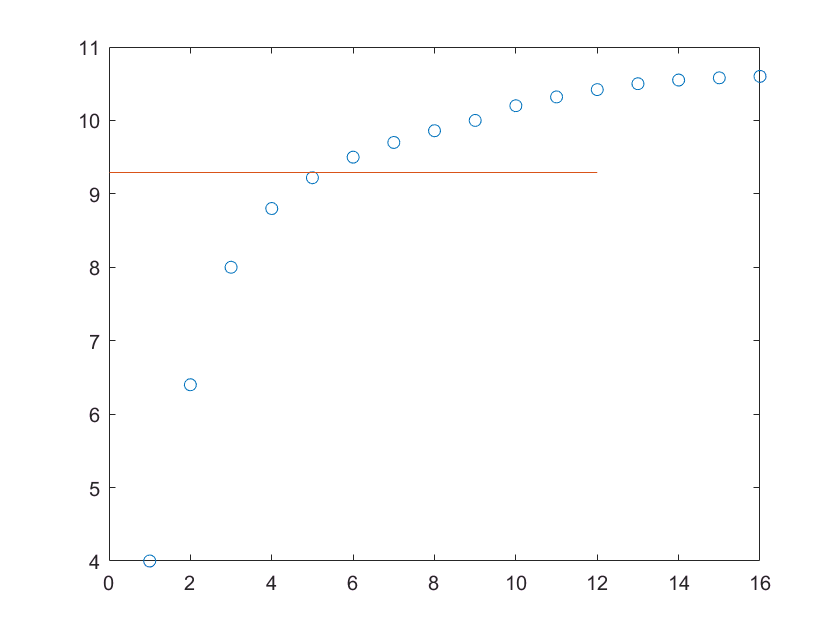

plot(t,y,'o')
hold on
yf=@(t)b(1)*exp(b(2)./t);
fplot(yf,[0,12])

function y=funy(b,t,y)
    %t=1:16;
    %y=[4 6.4 8 8.8 9.22 9.5 9.7 9.86 10 10.2 10.32 10.42 10.5 10.55 10.58 10.6]';
    y=b(1)*exp(b(2)./t)-y;
end
function y=funx(b,x)
   y=b(1)*exp(b(2)*x+b(3)*x.*x);
end